# Linear Regression (Simplest Implementation)

## Generating Data

% Taking any random data
X=randn(100,2);

% Adding noise to equation y = 3x1 + 7x2 + 4
Y=3*(X(:,1)+0.3*randn(100,1))+7*(X(:,2)+0.3*randn(100,1))+(4+0.3*randn(100,1));

% If data is not normalized, Zscore Normalization (Advised for SGD)
% data=[zscore(X),Y];
data=[X,Y];

% Define a symbolic varible for function plot
syms x1 x2

## CV Partition

- 70% to training set + 30% to testing set 

[train_set,test_set ] = holdout(data,70 );

X_train=train_set(:,1:end-1); Y_train=train_set(:,end);
X_test=test_set(:,1:end-1); Y_test=test_set(:,end);

% Number of training instances
N=length(X_train)

N = 70


% Number of testing instances
M=length(X_test)

M = 30

## 1.  Using Direct Method

- Append a vectors of one to *X_train *for calculating **bias**.

W=pinv([ones(N,1) X_train])*Y_train

W =     3.8348
    2.4676
    6.9775


## Mean Square Error

predicted_values=[ones(M,1) X_test]*W;
mse1=sqrt(mean((predicted_values-Y_test).^2))

mse1 = 2.9374

## Plot

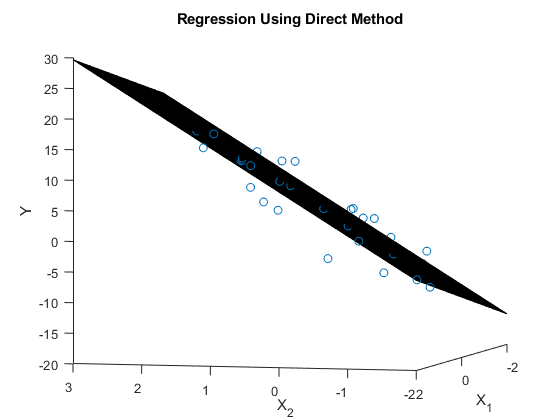

figure
hold on
scatter3(X_test(:,1),X_test(:,2),Y_test)
fsurf(W(1)+W(2)*x1 +W(3)*x2)
xlabel('X_1')
ylabel('X_2')
zlabel('Y')
title('Regression Using Direct Method')
view([-104.8 -5.2])
hold off

## 2. Using Inbuilt MATLAB Function

Test_mdl = fitlm(X_train,Y_train);
W=Test_mdl.Coefficients{:,1}

W =     3.8348
    2.4676
    6.9775


## Mean Square Error

predicted_values=predict(Test_mdl,X_test);
mse2=sqrt(mean((predicted_values-Y_test).^2))

mse2 = 2.9374

## Plot

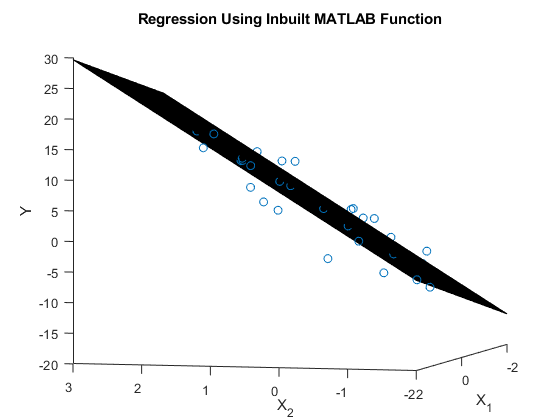

figure
hold on
scatter3(X_test(:,1),X_test(:,2),Y_test)
fsurf(W(1)+W(2)*x1 +W(3)*x2)
xlabel('X_1')
ylabel('X_2')
zlabel('Y')
title('Regression Using Inbuilt MATLAB Function')
view([-104.8 -5.2])
hold off

## 3. Using Stochastic Gradient Descent

- Learning Parameter, alpha = 0.1

- Append a vectors of one to *X_train *for calculating **bias**.

- Tolerence = 10^-5

X_train=[ones(N,1), X_train];

W=zeros(size(X_train,2),1);
W_old=ones(size(X_train,2),1);

while(norm(W_old-W) > 10^-5)
    W_old=W;
    W = W - 0.1/N*X_train'*(X_train*W - Y_train);
end
W

W =     3.8347
    2.4676
    6.9774


## Mean Square Error

predicted_values=[ones(length(X_test),1),X_test]*W;
mse3=sqrt(mean((predicted_values-Y_test).^2))

mse3 = 2.9374

## Plot

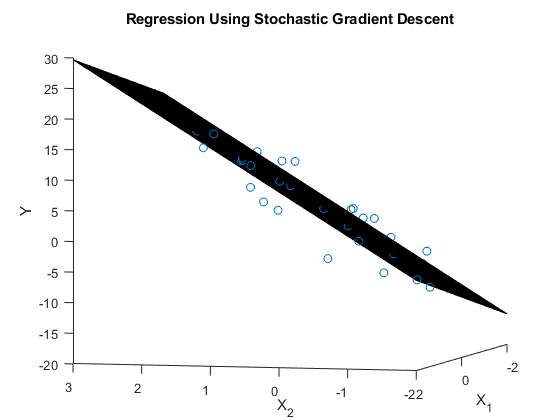

figure
hold on
scatter3(X_test(:,1),X_test(:,2),Y_test)
fsurf(W(1)+W(2)*x1 +W(3)*x2)
xlabel('X_1')
ylabel('X_2')
zlabel('Y')
title('Regression Using Stochastic Gradient Descent')
view([-104.8 -5.2])
hold off

## Comparing Mean Square

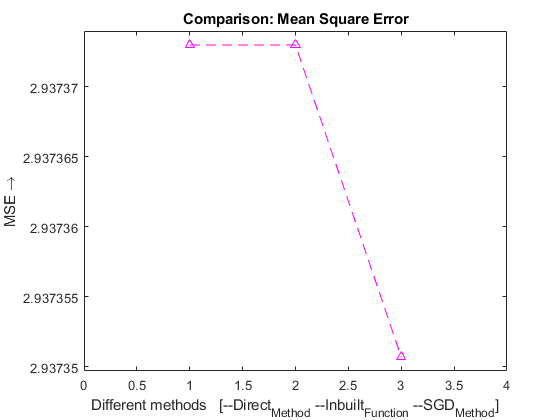

figure
mse=[mse1,mse2,mse3];
plot(mse,'--^m')
title('Comparison: Mean Square Error')
ylabel({'MSE \rightarrow'});
xlabel({'Different methods   [--Direct_{Method} --Inbuilt_{Function} --SGD_{Method}]'});
xlim([0, 4]); ylim([min(mse)-1e-6, max(mse)+1e-6]);

% Created by Bhartendu, Machine Learning & Computing

[Bhartendu, Machine Learning & Computing, Mathworks File Exchange](https://in.mathworks.com/matlabcentral/profile/authors/10083740-bhartendu)